# Direct and Inverse Kinematics

Adapted from: [Generate trajectory endeffector](https://nl.mathworks.com/help/supportpkg/robotmanipulator/ug/generate-trajectory-endeffector.html)

Initial Setup:

Clear workspace

clear all
clc
close all

## Robot selection

loadrobot(robotname) loads a robot model from the robot library as a rigidBodyTree object.

To import other robot models in Unified Robot Description Format (URDF), 

XML Macros (Xacro), or Simulation Description Format (SDF) file or Simscape Multibody model, the 'importrobot' function can be used.

### Create the Robot Model

 List of other built-in robot models: [Robot List](https://nl.mathworks.com/help/robotics/ref/loadrobot.html)

Or creatw one from scratch [Urdf](matlab:open('./urdf.mlx'))

kinovaGen3

- 7-axis manipulator

- Continuous payload: 4 kg / 8.8 lbs

- Maximum reach: 902 mm

- Weight: 8.2 kg / 18 lbs

- Power consumption: 36 W

`abbIrb120T`

- 6-axis manipulator

- Continuous payload: 3 kg / 6.6 lbs

- Maximum reach: 580 mm

- Weight: 25 kg / 55.1 lbs

- Power consumption: 30 W

`kukaIiwa7`

- 7-axis manipulator

- Continuous payload: 7 kg

- Maximum reach: 800 mm

- Weight: 23.9 kg 

- Power consumption: 400-600 W

Create a Rigid Body Tree for the robot, set the home configuration and 

calculate the transformation at the home configuration:

robot = importrobot('ur2.urdf');
robot.Gravity = [0 0 -9.81];
robot.DataFormat = 'column';

To see robot details:

showdetails(robot)

--------------------
Robot: (8 bodies)

 Idx        Body Name         Joint Name         Joint Type        Parent Name(Idx)   Children Name(s)
 ---        ---------         ----------         ----------        ----------------   ----------------
   1        base_link        world_joint              fixed                world(0)   link1(2)  
   2            link1             joint1           revolute            base_link(1)   link2(3)  
   3            link2             joint2           revolute                link1(2)   link3(4)  
   4            link3             joint3           revolute                link2(3)   link4(5)  
   5            link4             joint4           revolute                link3(4)   link5(6)  
   6            link5             joint5           revolute                link4(5)   link6(7)  
   7            link6             joint6           revolute                link5(6)   ee_link(8)  
   8          ee_link           ee_joint              fixed              

To define a configuration we have to option:

- Define arbitrary home configuration  (radians)

- Random home configuration

% Arbitrary home configuration
q_home = homeConfiguration(robot)

q_home =      0
     0
     0
     0
     0
     0



% Random    home configuration
%q_home = randomConfiguration(robot);

To interact with the robot model:

% interactiveGUI = interactiveRigidBodyTree(robot);

Visualize robot configuration:

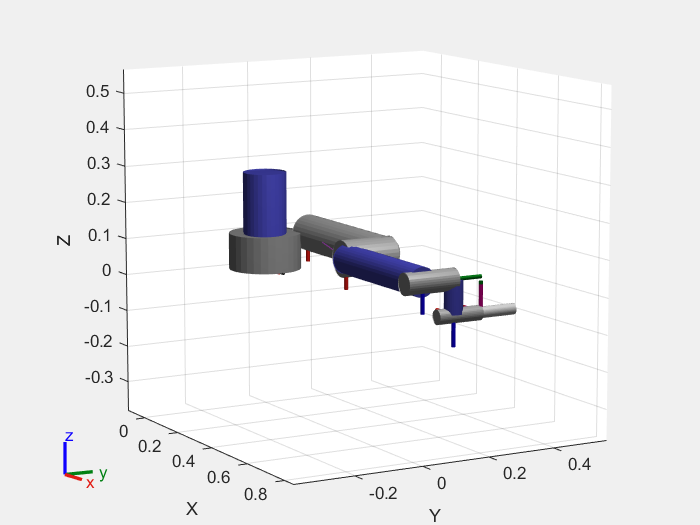

show(robot,q_home);
axis auto;
view([60,10]); % camera line of sight view(az,el)

 To see the names of links we can use the command:

% robot.BodyNames
% (or "showdetails(robot)")

The end-effector is the last body. Its name is 'EndEffector_Link' 

So we can define:

% eeName = 'EndEffector_Link';

A quicker way is to take the last body 

eeName = string(robot.BodyNames(length(robot.BodyNames)));

 The home configuration is described by a homogeneous transformation matrix:

T_home = getTransform(robot, q_home, eeName);

getTransform computes the homogeneous transformation matrix `T_home` that describes the end-effector's position and orientation in the world frame at the home configuration.

We can determine the position of the end-effector 

( first 3 components of the last 4x1 column):

toolPositionHome = T_home(1:3,4);

## Waypoint

Set of Waypoints

waypoints = toolPositionHome + ... 
            [  0.0  0.0  0.0 ; 
              -0.1  0.2  0.2 ; 
              -0.2  0.0  0.1 ;           
              -0.1 -0.2  0.2 ; 
               0.0  0.0  0.0 ]';

Defines a series of waypoints in Cartesian space, based on the home position with some offsets in the x, y, and z directions.

-----------------------------------------------------------------------------------------------------------

# EXERCISE: 

how to have the robot stopping for a few seconds at a specified point?

-----------------------------------------------------------------------------------------------------------

Let's define the desired orientation of the end-effector in the waypoints.

The orientation is represented in Euler angles and the convention used  is the Tait-Bryan, extrinsic ZYX. Extrinsic rotations apply to axis in world coordinate system.

orientations = [pi/2    0   pi/2;
               (pi/2)+(pi/4)      0   pi/2; 
                pi/2    0   pi;             
               (pi/2)-(pi/4)       0    pi/2;
                pi/2    0   pi/2]';

Waypoint Times:

waypointTimes = 0.5 * [0 5 15 20 25];

Specifies the times at which the robot should reach each waypoint.

## Trajectory Parameters:

#### Time Discretization:

Number_of_steps = 40; 
ts = waypointTimes(length(waypointTimes))/Number_of_steps; 
% Vector of discretized times:
trajTimes = 0:ts:waypointTimes(end);

Discretizes the trajectory time into `Number_of_steps` intervals, setting the time step `ts`.

#### End-Effector Velocities at Waypoints:

waypointVels = 0.8 *[ 0  1  0;
                     -1  0  0;
                      0 -1  0;                     
                      1  0  0;
                      0	 1  0]';

Specifies the velocities of the end-effector at each waypoint. These are arbitrary chosen directions of motion.

#### Waypoint Accelerations:

Acceleration at waypoints is computed from velocity. But first we must allocate memory for accelerations:

waypointAccels = zeros(size(waypointVels));
waypointAccelTimes = diff(waypointTimes)/4;

## Inverse Kinematics Setup:

#### Create Inverse Kinematics Solver:

The algorithm for solving inverse kinematics can be specified: either  'BFGSGradientProjection' (default) or 'LevenbergMarquardt'. 

ik = inverseKinematics('RigidBodyTree',robot);

Weights for Pose Tolerances:

Weights for pose tolerances, specified as a six-element vector. 

-  first three -> error in orientation for the desired pose

-  last three -> error in the xyz position for the desired pose

ikWeights = [1 1 1 1 1 1];

All weights are set to 1, indicating equal importance for position and orientation.

InverseKinematics has several additional options (e.g. max number of interations, joint limits, tolerances, etc.)

#### Initial Guess for IK:

Sets the initial guess for the inverse kinematics solver as the home configuration.

ikInitGuess = q_home';

Angles are adapted so to be between -pi e +pi:

ikInitGuess(ikInitGuess > pi) = ikInitGuess(ikInitGuess > pi) - 2*pi;
ikInitGuess(ikInitGuess < -pi) = ikInitGuess(ikInitGuess < -pi) + 2*pi;

## Plot Setup

Initialize Plot for Waypoints and Trajectory

plotMode = 1; % 0 = None, 1 = Trajectory, 2 = Coordinate Frames
show(robot,q_home,'Frames','off','PreservePlot',false);
hold on

if plotMode == 1
    hTraj = plot3(waypoints(1,1),waypoints(2,1),waypoints(3,1),'b.-');
end
plot3(waypoints(1,:),waypoints(2,:),waypoints(3,:),'ro','LineWidth',2);
axis auto;
view([30 15]);

## Solve Inverse Kinematics for Waypoints:

The inverse kinematics problem can be solved with reference to positions only, or we can also include the orientation of the EE  by setting the following Boolean flag to "true":

includeOrientation = false; 
numWaypoints = size(waypoints,2); % Number of waypoints
numJoints = numel(robot.homeConfiguration);

 Allocate memory:

jointWaypoints = zeros(numJoints,numWaypoints);

- The waypoints are defined in Cartesian coordinates and need to be converted to a homogeneous transformation using the command **"trvec2tform"**.

- The orientations are described using Euler's angles (Tait-Bryan, extrinsic ZYX).

- These orientations must be converted to a homogeneous transformation using the command **"eul2tform"**.

for idx = 1:numWaypoints
    if includeOrientation
        tgtPose = trvec2tform(waypoints(:,idx)') * eul2tform(orientations(:,idx)');
    else
        tgtPose = trvec2tform(waypoints(:,idx)') * eul2tform([pi/2 0 pi/2]);
    end
    [config,info] = ik(eeName,tgtPose,ikWeights',ikInitGuess');
    jointWaypoints(:,idx) = config';
end

## Trajectory Interpolation:

The joint trajectories are interpolated between the waypoints using different methods (trapezoidal, cubic, quintic, B-spline). 

The code includes options for different interpolation types:

- Trapezoidal (trap)

- Cubic

- Quintic

- B-Spline (bspline)

trajType = 'trap';
switch trajType
    case 'trap'
        [q,qd,qdd] = trapveltraj(jointWaypoints,numel(trajTimes), ...
            'AccelTime',repmat(waypointAccelTimes,[numJoints 1]), ... 
            'EndTime',repmat(diff(waypointTimes),[numJoints 1]));
                            
    case 'cubic'
        [q,qd,qdd] = cubicpolytraj(jointWaypoints,waypointTimes,trajTimes, ... 
            'VelocityBoundaryCondition',zeros(numJoints,numWaypoints));
        
    case 'quintic'
        [q,qd,qdd] = quinticpolytraj(jointWaypoints,waypointTimes,trajTimes, ... 
            'VelocityBoundaryCondition',zeros(numJoints,numWaypoints), ...
            'AccelerationBoundaryCondition',zeros(numJoints,numWaypoints));
        
    case 'bspline'
        ctrlpoints = jointWaypoints; % Can adapt this as needed
        [q,qd,qdd] = bsplinepolytraj(ctrlpoints,waypointTimes([1 end]),trajTimes);
        % Remove the first velocity sample
        qd(:,1) = zeros (7,1);    
    otherwise
        error('Invalid trajectory type! Use ''trap'', ''cubic'', ''quintic'', or ''bspline''');
end


## Plotting the Trajectory:

In a loop over the trajectory time steps, the joint configurations `q` are used to update the robot’s pose in the plot.

The Cartesian trajectory of the end-effector is also updated in 3D space.

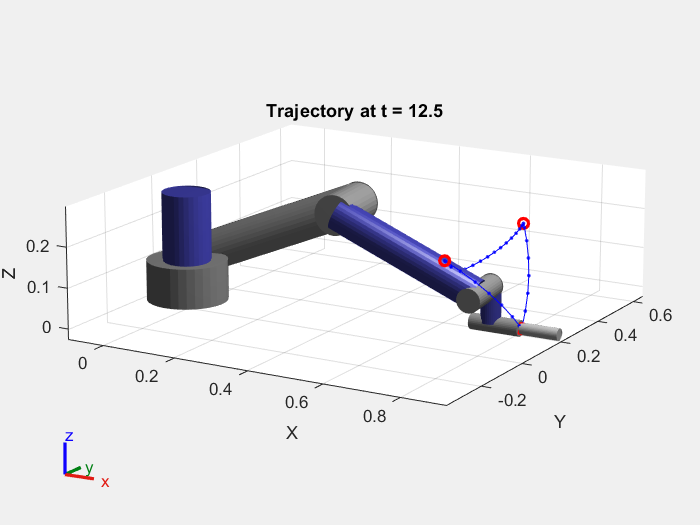

for idx = 1:numel(trajTimes)  
 
    config = q(:,idx)';
    
    % Find Cartesian points for visualization
    eeTform = getTransform(robot,config',eeName);
    % plotMode == 1 means "show trajectory"; "0" was: nothing; 
    % "2" was: show axes
    if plotMode == 1 
        eePos = tform2trvec(eeTform);
        set(hTraj,'xdata',[hTraj.XData eePos(1)], ...
                  'ydata',[hTraj.YData eePos(2)], ...
                  'zdata',[hTraj.ZData eePos(3)]);
    elseif plotMode == 2
        plotTransforms(tform2trvec(eeTform),tform2quat(eeTform),'FrameSize',0.05);
    end
 
    % Show the robot
    show(robot,config','Frames','off','PreservePlot',false);
    title(['Trajectory at t = ' num2str(trajTimes(idx))])
    drawnow   
    
end

## Compute Joint Torques and Power:

% Let's compute joint torques and power.
%
% Number of time intervals:
N = numel(trajTimes);
% jointTorq = inverseDynamics(gen3,q(:,1)',qd(:,1)',qdd(:,1)')
% preallocate memory:
jointTorques = zeros(numJoints,N);
Power = zeros(1,N); % vector with N 0's
TotalPower = zeros(1,N);
JointPower = zeros(numJoints,N);
 for i = 1:N
     jointTorques(:,i) = inverseDynamics(robot,q(:,i),qd(:,i),qdd(:,i));
     Power(i) = dot(qd(:,i),jointTorques(:,i)); % scalar product
     JointPower(:,i) = qd(:,i).*jointTorques(:,i); % element-wise product
     TotalPower(i) = sumabs(JointPower(:,i)); % sum of absolute values
 end

## Plot Power and Joint Torques:

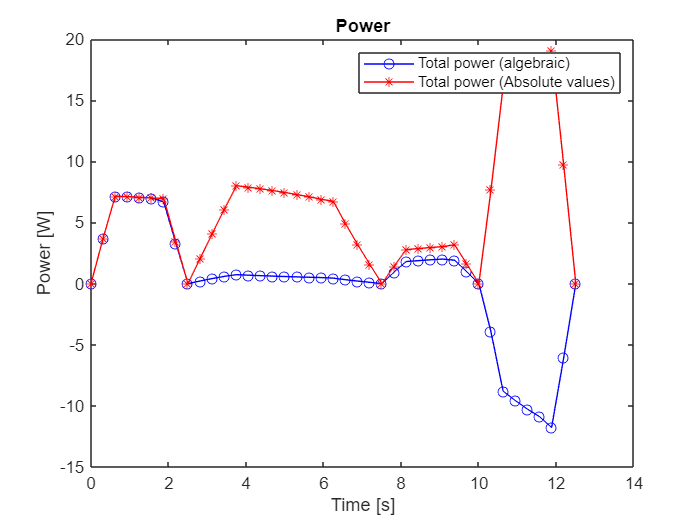

figure
plot(trajTimes,Power,'b-o')
hold on
plot(trajTimes,TotalPower,'r-*')
title('Power')
xlabel('Time [s]')
ylabel('Power [W]')
hold off
legend('Total power (algebraic)','Total power (Absolute values)')

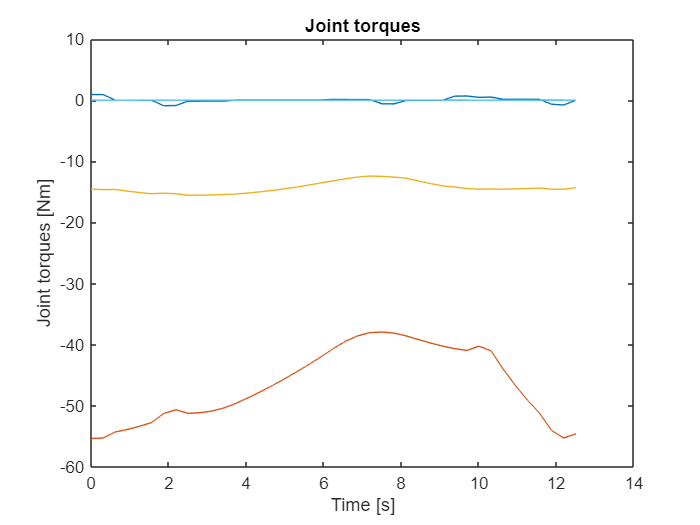

figure
plot(trajTimes,jointTorques)
title('Joint torques')
xlabel('Time [s]')
ylabel('Joint torques [Nm]')

-----------------------------------------------------------------------------------------------------------

# EXERCISE

adapt the script so to interpolate waypoints in the task space

-----------------------------------------------------------------------------------------------------------